# MXB161 IW3 Image Processing 1

This is your Individual Worksheet (IW).  Complete this worksheet at your own pace.  After you've completed the worksheet, you'll be ready to take the Quiz for this topic, which can be found on Canvas on the Topic 3 - Image Processing 1 page.

## Getting started

This worksheet is designed to be completed in conjunction with the associated online lecture on Canvas.

If you haven't yet started the online lecture, please start that first.  You'll be directed to return to this worksheet at the appropriate time in the lecture.

## 3.1 Array indexing

Before we get started with our image processing, we'll do some warm-up exercises with MATLAB's array indexing. Run the following commands to create an array `A` with 5 rows and 8 columns, filled with "helpful" values:

[X,Y] = meshgrid(1:8, 1:5)

X =      1     2     3     4     5     6     7     8
     1     2     3     4     5     6     7     8
     1     2     3     4     5     6     7     8
     1     2     3     4     5     6     7     8
     1     2     3     4     5     6     7     8


Y =      1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5


A = X + 10*Y

A =     11    12    13    14    15    16    17    18
    21    22    23    24    25    26    27    28
    31    32    33    34    35    36    37    38
    41    42    43    44    45    46    47    48
    51    52    53    54    55    56    57    58


When talking about the location of elements in an array, the convention is to state the row index first, then the column index.  So, we would say something like "the element in the 3rd row, 7th column of A".  In MATLAB, this is expressed like so:

A(3,7)

ans = 37

The values in this array `A` have been chosen so that `A(3,7)` equals 37 (and so on for all elements) to make it clearer what's going on.

To index an entire row, use the colon symbol for the column index.  For example, the 4th row of `A` is given by

A(4,:)

ans =     41    42    43    44    45    46    47    48


You might like to read the colon symbol in your mind as "*all*".  Then in words, this command reads something like "4th row of `A`, all columns".  Write the command to print the 6th column of `A` (i.e. "6th column of `A`, all rows").

A(:,6)

ans =     16
    26
    36
    46
    56


You can also index *partial* rows and columns using the colon notation.  This command prints rows 2 to 4 in the 3rd column of `A`.

A(2:4, 3)

ans =     23
    33
    43


Write the command to print columns 3 to 7 in the 1st row of `A`.

A(1, 3:7)

ans =     13    14    15    16    17


Values can also be *assigned* to part of an array using these expressions.  For example, here we assign all of the 2nd row of `A` to be zero.

A(2,:) = 0

A =     11    12    13    14    15    16    17    18
     0     0     0     0     0     0     0     0
    31    32    33    34    35    36    37    38
    41    42    43    44    45    46    47    48
    51    52    53    54    55    56    57    58


Write the command to assign rows 3 to 5 in the 8th column of `A` to be `-1`.

A(3:5, 8) = -1

A =     11    12    13    14    15    16    17    18
     0     0     0     0     0     0     0     0
    31    32    33    34    35    36    37    -1
    41    42    43    44    45    46    47    -1
    51    52    53    54    55    56    57    -1


Your array should now look like this:

`A =`

`    11    12    13    14    15    16    17    18`

`     0     0     0     0     0     0     0     0`

`    31    32    33    34    35    36    37    -1`

`    41    42    43    44    45    46    47    -1`

`    51    52    53    54    55    56    57    -1`

Arrays in MATLAB also support *logical expressions*. For example, we can create a logical array `B` with ones where `A` is less than 40 and zeros elsewhere.

B = A < 40

B = 5×8 logical array
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   1


Think of the expression `A < 40` as a true/false question.  MATLAB responds with ones (true) where `A` is less than 40, and zeros (false) where it isn't.  Confirm visually that the ones in the array `B` are all in the locations where `A` is less than 40.

We can combine several such expressions using `&` (and) and `|` (or).  For example

C = A < 40 & A > 0

C = 5×8 logical array
   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0


This creates the logical array `C` with ones where `A` is less than 40 *and* `A` is greater than 0.

What do you think the command

D = A > 50 | A == -1

D = 5×8 logical array
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   1
   1   1   1   1   1   1   1   1


will return?  Try it out, and see that you understand the result.

**Note: Be careful of the distinction between **`=`** (which is used for *****assignment*****), and **`==`** (which is used to test for *****equality*****).**

**Well done on finishing this section**.  Now you can return to the online lecture.

## 3.2 Black and white images

Our image processing discussion commences by looking at pure black and white images. In MATLAB, these are represented by arrays of logical values. As we just saw, logical values can be either 0 (`false`) or 1 (`true`). When interpreted as an image, values of 0 are black and values of 1 are white. Here's a simple example. First, we'll create an array of random `double`s between zero and one:

A = rand(10, 10)

A =     0.8147    0.1576    0.6557    0.7060    0.4387    0.2760    0.7513    0.8407    0.3517    0.0759
    0.9058    0.9706    0.0357    0.0318    0.3816    0.6797    0.2551    0.2543    0.8308    0.0540
    0.1270    0.9572    0.8491    0.2769    0.7655    0.6551    0.5060    0.8143    0.5853    0.5308
    0.9134    0.4854    0.9340    0.0462    0.7952    0.1626    0.6991    0.2435    0.5497    0.7792
    0.6324    0.8003    0.6787    0.0971    0.1869    0.1190    0.8909    0.9293    0.9172    0.9340
    0.0975    0.1419    0.7577    0.8235    0.4898    0.4984    0.9593    0.3500    0.2858    0.1299
    0.2785    0.4218    0.7431    0.6948    0.4456    0.9597    0.5472    0.1966    0.7572    0.5688
    0.5469    0.9157    0.3922    0.3171    0.6463    0.3404    0.1386    0.2511    0.7537    0.4694
    0.9575    0.7922    0.6555    0.9502    0.7094    0.5853    0.1493    0.6160    0.3804    0.0119
    0.9649    0.9595    0.1712    0.0344    0.7547    0.2238    0.2575    0.4733    0.5

You should now have a 10 by 10 array of random numbers.  Because they're random, roughly half of these values should be greater than 0.5, and half not.  Our logical array is created with the command

BW = A > 0.5

BW = 10×10 logical array
   1   0   1   1   0   0   1   1   0   0
   1   1   0   0   0   1   0   0   1   0
   0   1   1   0   1   1   1   1   1   1
   1   0   1   0   1   0   1   0   1   1
   1   1   1   0   0   0   1   1   1   1
   0   0   1   1   0   0   1   0   0   0
   0   0   1   1   0   1   1   0   1   1
   1   1   0   0   1   0   0   0   1   0
   1   1   1   1   1   1   0   1   0   0
   1   1   0   0   1   0   0   0   1   0


This creates the logical array `BW` with ones where `A` is larger than 0.5, and zeros elsewhere.  Using `imshow` to view this array as an image, we get something like the following (remember, this array was created using random numbers, so don't expect exactly the same image):

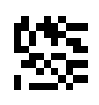


$$\text{10 squares by 10 squares randomly coloured either black or white.}$$


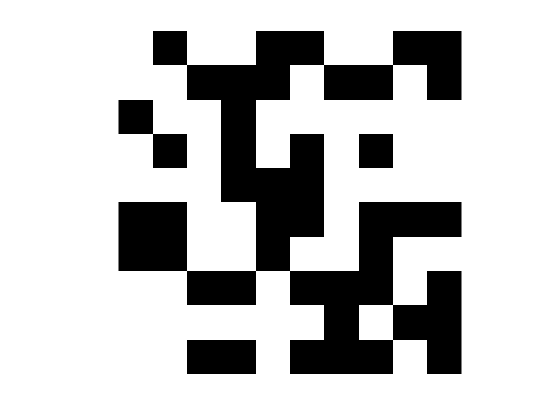

imshow(BW, 'InitialMagnification', 'fit') % try it without the 'InitialMagnification' option to

                                          % see how small a 10x10 image really is!

It's a small random chequerboard-type pattern.  Each individual black or white square in this image is called a *pixel*. The size of this image is only 10 pixels across and 10 pixels down.  To make a larger one, we need to use a larger array.  Recreate your variable `A` using a random array of size 200 by 1000 (that is, 200 rows and 1000 columns). Then recreate `BW` in the same way as before.

A = rand(200, 1000);
BW = A > 0.5

BW = 200×1000 logical array
   1   1   1   0   0   1   0   1   1   0   1   0   1   1   1   1   1   1   0   0   0   1   0   1   1   1   0   1   0   0   1   1   0   0   1   0   0   1   1   1   1   1   0   1   1   0   1   0   1   1
   1   1   1   1   0   0   0   0   1   1   1   0   0   0   1   0   1   0   1   1   1   0   1   0   0   1   0   0   1   1   1   1   0   0   0   1   0   0   1   0   1   0   0   1   1   0   1   1   1   0
   1   1   1   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   1   0   1   1   1   1   0   1   1   1   1   1   1   0   1   1   0   0   1   0   0   0   0   0   0   1   1   0   1   0
   1   0   1   0   0   0   0   1   1   0   1   0   0   1   1   0   0   1   0   0   1   1   1   0   1   1   0   0   1   0   1   1   1   1   0   0   0   1   1   0   0   1   0   1   1   0   0   1   0   1
   1   1   1   0   0   1   1   1   1   1   0   0   1   1   1   1   0   0   1   0   0   0   1   1   0   1   0   0   1   1   0   0   1   0   1   0   0   1   1   0   0   1

Now use `imshow` to view the new, larger image.  It should look something like this:

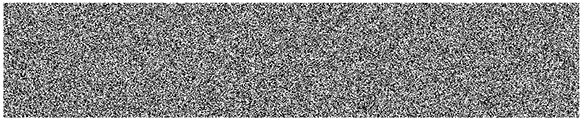

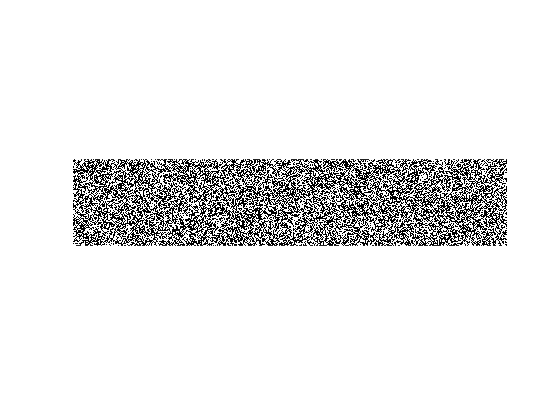

imshow(BW, 'InitialMagnification', 'fit') % try it without the 'InitialMagnification' option to

Click the arrow on the image to open it in a dedicated Figure window.  Then use the image toolbar to zoom in on a given region of this image, and confirm that each pixel is either purely black or white.

**Well done on finishing this section**.  Now you can return to the online lecture.

## 3.3 Greyscale images

To create greyscale images, we need to have more values than simply zero or one.  In MATLAB, we use the `uint8` type to represent values between 0 and 255, where now 0 represents black, 255 represents white, and values in-between represent shades of grey.

The `randi` command can be used to create random arrays of `uint8`.  Here's a 10 by 10 example:

grey = randi([0,255], 10, 10, 'uint8')

grey = 10×10 uint8 matrix
   155    75     3    29   121    39   172   232   216   147
   215   221   254    27   190    76    44   190   146   231
   248   242   161    37    47   252   182   158   252    16
    53    50   160   134   119   243    64    93    48   180
   108   163   225   111   147   154    41    65   198    30
    34   161    94    86    12   156   134   226     7   255
   171   113   108   218    80   120   195     9   246   137
   100   207   228   181   187    28    44   160   128   233
    25    63   138    58   106    50   122    93    94     7
    97   108    82    66   244    72   120    27   152   202


Confirm by inspection that all values are between 0 and 255 inclusive.  Now use `imshow` to view this image.

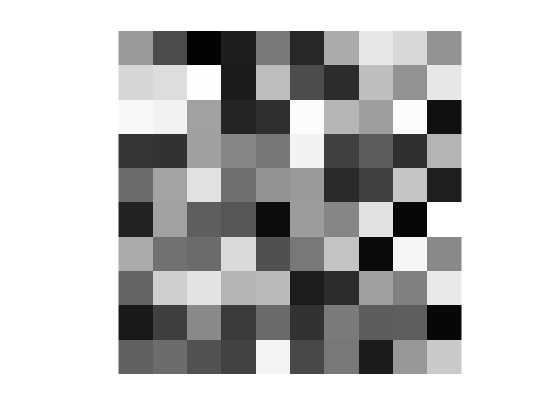

imshow(grey, 'InitialMagnification', 'fit')

It should look something like this:

Since this is only a small image, the shades of grey are clearly visible in the pixels.  Now create a larger example, using a random array of size 200 by 1000 (that is, 200 rows and 1000 columns).  Call this array `grey`.

Then view the image using `imshow`.  You should see something like this:

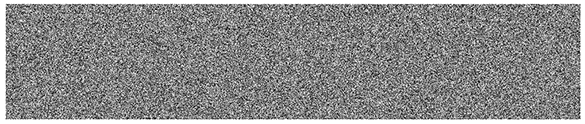

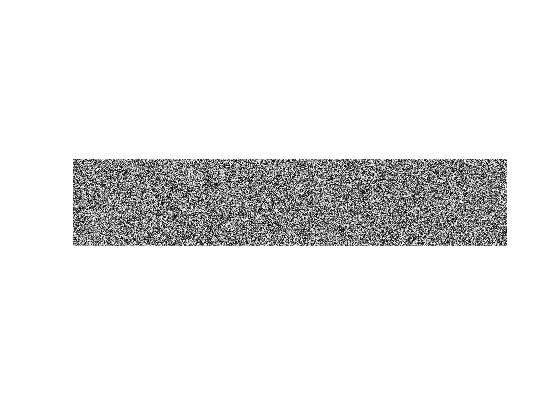

grey = randi([0,255], 200, 1000, 'uint8');
imshow(grey, 'InitialMagnification', 'fit')

From a distance this figure looks much the same as the earlier pure black and white figure.  But open it in a Figure window, and zoom in closely.  You'll see that each pixel is in fact a shade of grey rather than simply black or white.

Let's manipulate this image a little bit.  First, we'll draw a horizontal, light grey stripe by assigning the value 200 to the elements in rows 50 to 70.  Here's what you should see:

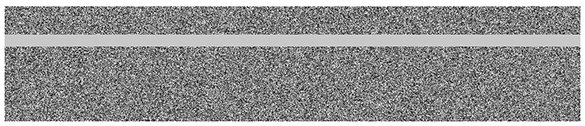

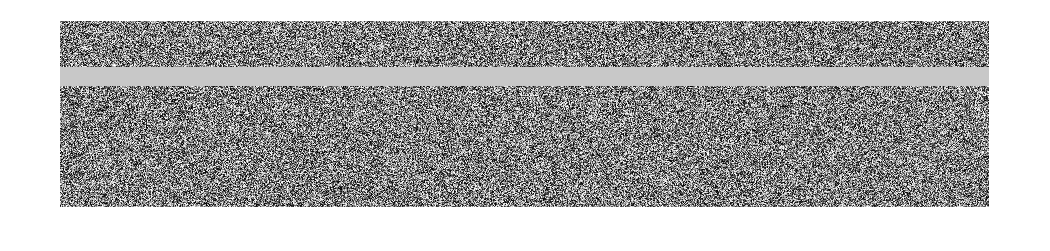

grey(50:70, :) = 200; % using a semicolon to terminate the command so we don't see the printed output
imshow(grey)

Enter the command to draw a vertical, dark grey stripe (value of 50) covering columns 600 to 800.  You should see this:

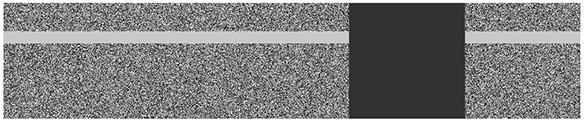

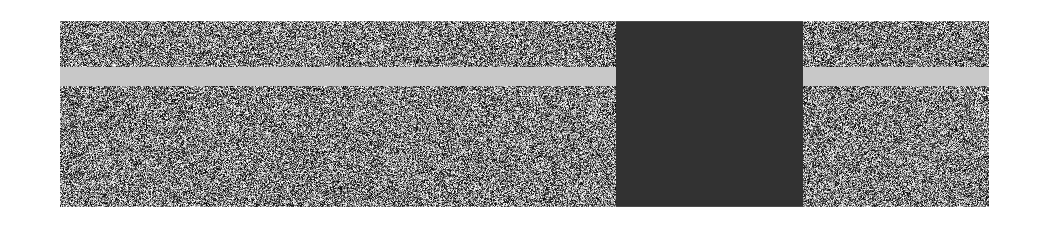

grey(:, 600:800) = 50; 
imshow(grey)

**Well done on finishing this section**.  Now you can return to the online lecture.

## 3.4 Colour images

Colour images are represented in MATLAB by a *three-dimensional* `uint8` array.  The third dimension has three "pages" or "channels", one for red, one for green and one for blue. All other colours are formed by mixing different quantities of these three *primary colours*. To create a small random colour image, we can use the command

colour = randi([0,255], 10, 10, 3, 'uint8')

colour = 10×10×3 uint8 array
colour(:,:,1) =

    82   107     5    15   109    64   187    42    90    46
   219   143   217    66    40   178   225   225    82   122
   164   154   187    80   203     4   172   157   178   223
   115     9    32   128     4    49    66   118   149   175
    74   155    91   127   229    28   150    92   221   206
   159   162    82   122     5    15   177   193   118    40
    64   122   181   163     5    93   223    64   150   231
   118   207   198    54     0   192   199   206   183   220
   212    66   104   178    88   172    81    25    23   146
    50   193    15   135    33     8   119     4   175   170


colour(:,:,2) =

   113   159   230   111   130   186   182    80   245   226
    69   108   158   242    67   112   249   178    10   207
   148   112    22   117    57    20    59    24   100   123
   116    87   159   114    62   151   158    34   182   180
   188   118   229   114   254   250   195     8     6   198
   119   241   251  

This creates a three-dimensional array with 3 pages each of size 10 by 10.  View this image with `imshow` and you should see something like this:

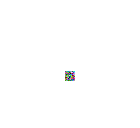

imshow(colour)

Once again it's random, so don't expect to see the exact same image as shown here.  Create a larger colour image of size 200 by 1000 and view it on-screen.

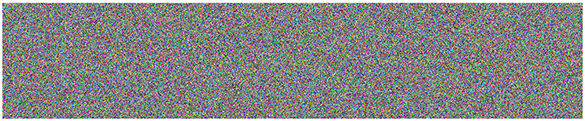

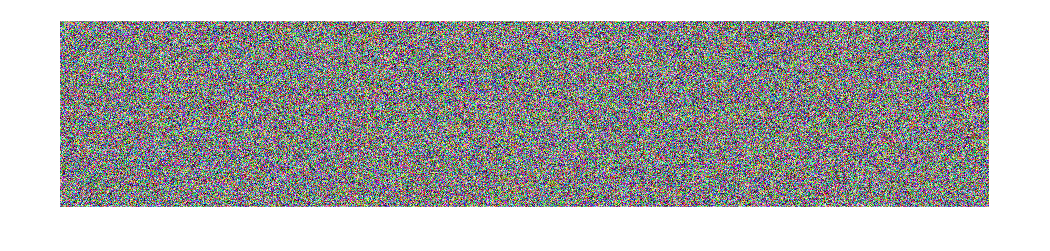

colour = randi([0,255], 200, 1000, 3, 'uint8');
imshow(colour)

Open the figure in its own Figure window.  Zoom in to the figure, until the individual pixels are big enough to distinguish.  Now select the **Data Tips** tool:

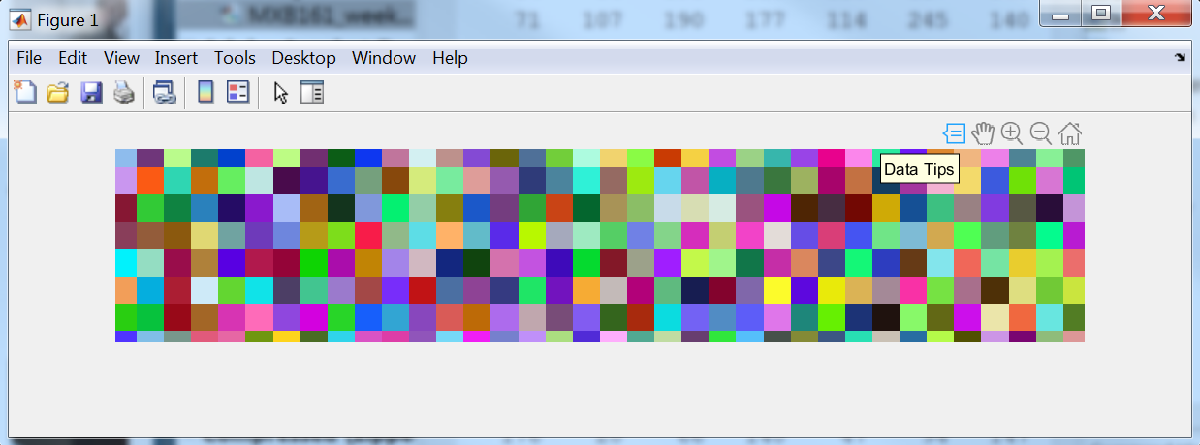

Click on any pixel you like using this tool.  You should see a small window with the "X,Y coordinates" of the pixel, and the RGB (red, green blue) values.

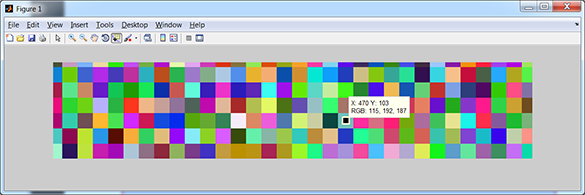

In this example, the pixel has "X coordinate" 470 and "Y coordinate" 103.  In MATLAB, this really means that this pixel is in *row* 103 (think about it: the row determines the pixel's *vertical* position, so it's the Y value) and column 470.  We can confirm that the RGB values shown by MATLAB's Data Tips tool are correct by indexing our array at this location:

`colour(103, 470, :)`

`ans(:,:,1) =`

`  115`

`ans(:,:,2) =`

`  192`

`ans(:,:,3) =`

`  187`

Do the same with the pixel you clicked on, and confirm you get the correct results when you index the array at that location.

pixel = colour(154, 671, :)

pixel = 1×1×3 uint8 array
pixel(:,:,1) =

   112


pixel(:,:,2) =

   223


pixel(:,:,3) =

   113


**Well done on finishing this section**.  Now you can return to the online lecture.

## 3.5 Masking

In image-processing, *masking* is the process of using logical arrays to identify regions of images. Load the file **balloons.png** from the current directory into the variable `balloons `using the **imread** function.  Note the difference betwen **imread** and **imshow**.  The former loads the image into a variable of your choosing (which you can than view, manipulate, display, etc. as you wish).  The latter just displays the image.

balloons = imread('balloons.png'); % note: imread rather than imshow

We can confirm that `balloons` represents a colour image, by finding its `size`.  Do this now, and explain how the answer tells you it's a colour image.

size(balloons) % This is an image with a size of y = 692 and x = 689 with the last 3 representing the RGB values from 0 to 255

ans =    692   689     3


Incidentally, we can also query the *class* of the `balloons` variable, to confirm that it's of class `uint8` (and not `double`, `logical` or something else).

class(balloons)

ans = 'uint8'

View the image now using **imshow**.  Note that you have the image loaded into the variable `balloons` already, so you can use that rather than loading it again from file.

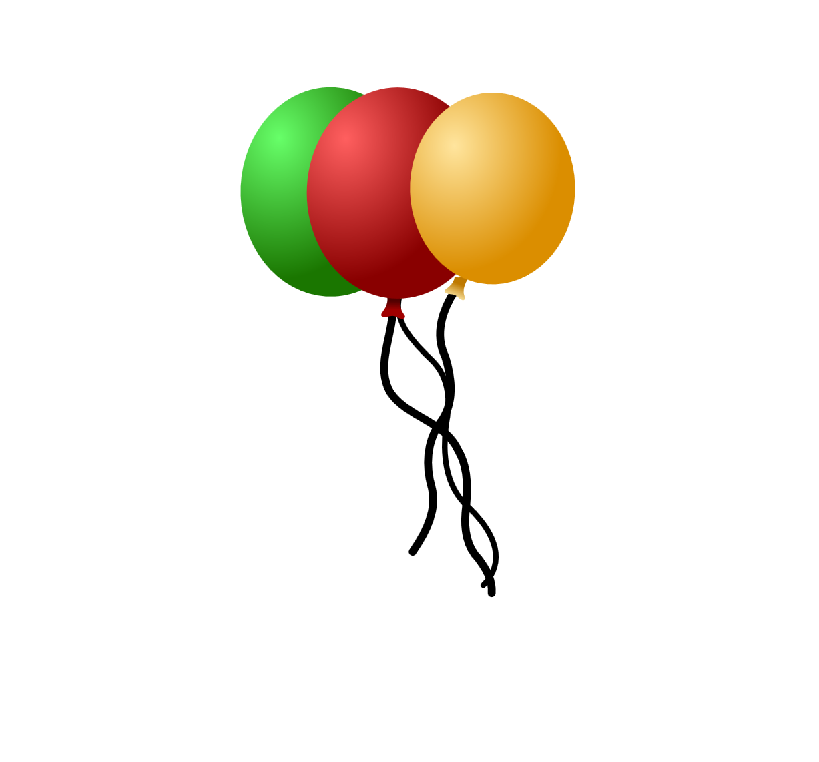

imshow(balloons)  % using the variable you created earlier; it's not loading it from the file again

  Confirm it looks like balloons.

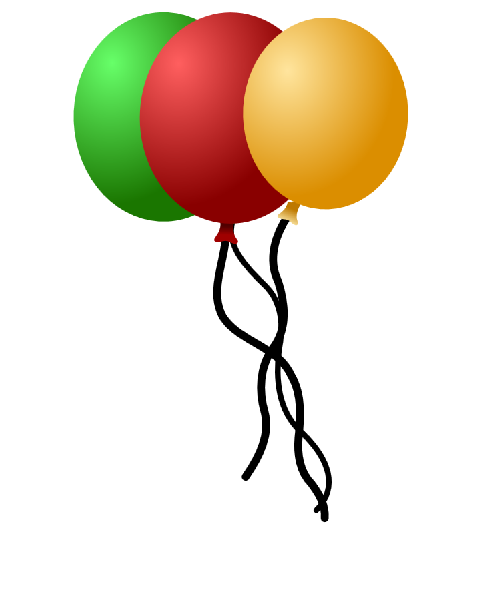

Suppose we want to identify which portion of the image corresponds to the red balloon. Open the figure in a Figure window and use the Data Tips to click around several locations within the red balloon and notice what the range of RGB values are.  You should find that the red values are all greater than 80, and the green and blue values are all less than 100. We can use this information to "mask out" the red balloon from the rest of the image.

First, we will create a `mask`. This is a logical array identifying where in the image the red balloon can be found.

mask = balloons(:,:,1) > 80 & balloons(:,:,2) < 100 & balloons(:,:,3) < 100

mask = 692×689 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

In words, the command    `mask = balloons(:,:,1) > 80 & balloons(:,:,2) < 100 & balloons(:,:,3) < 100`

says that the `mask` is 1 (true) when the red component of balloons is greater than 80 *and* the green component of balloons is less than 100 *and* the blue component of balloons is less than 100.

Remember from earlier that the mask itself, being a logical array, can be viewed as a purely black and white image.  Do that now.

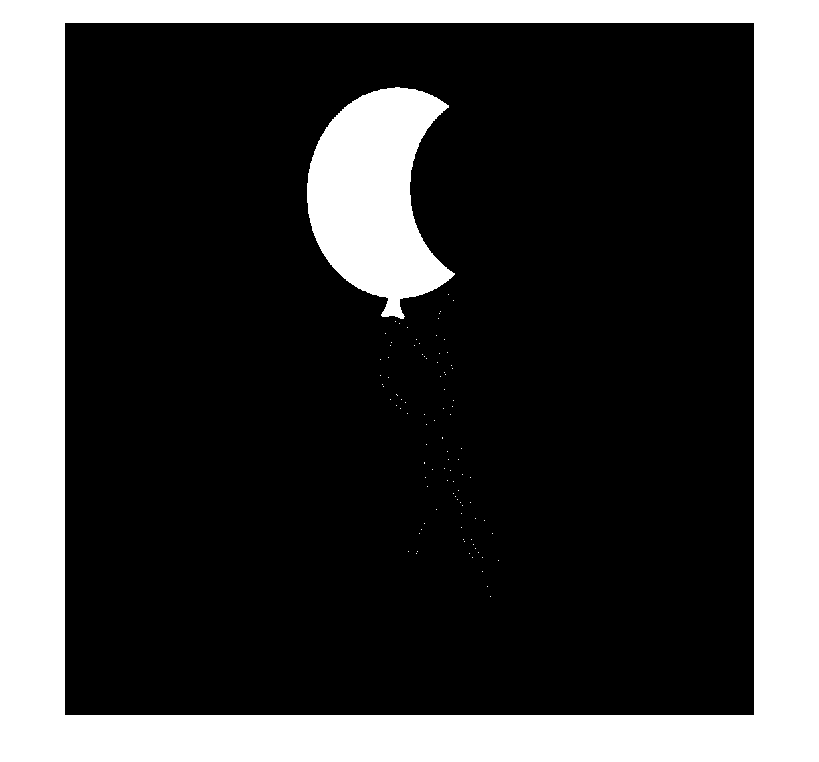

imshow(mask)

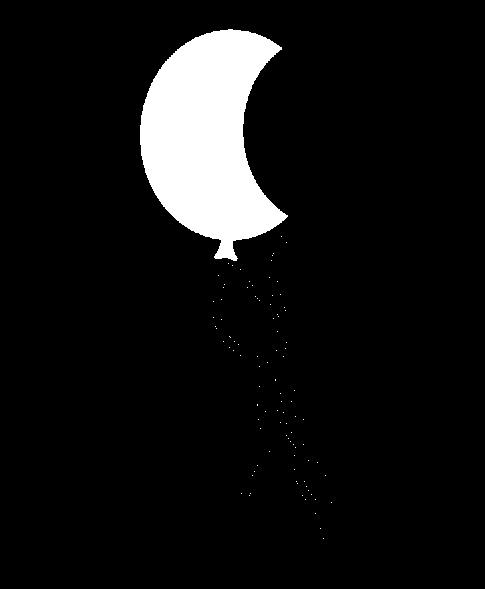

You can see that the mask has indeed picked out the red balloon from the image (as well as some small bits of the balloon string).

**Well done on finishing this section**.  Now you can return to the online lecture.

## 3.6 Digital watermarking

Digital watermarking is a process of "hiding" extra information in the redundant parts of an image.  The example in the lecture showed how to conceal the QUT logo in a greyscale image.  The exercise for this section is to reproduce that example yourself.  Refer back to the lecture video as often as you need.

Begin by loading in the two required images: `room360greyscale.png` and `qutlogobw.png`.

roomGSImg = imread("room360greyscale.png");
qutLogoImg = imread("qutlogobw.png");

Use the `bitget` command to extract the least significant bit of the greyscale image, and display it as a black and white image.  Confirm visually that it carries no useful information.

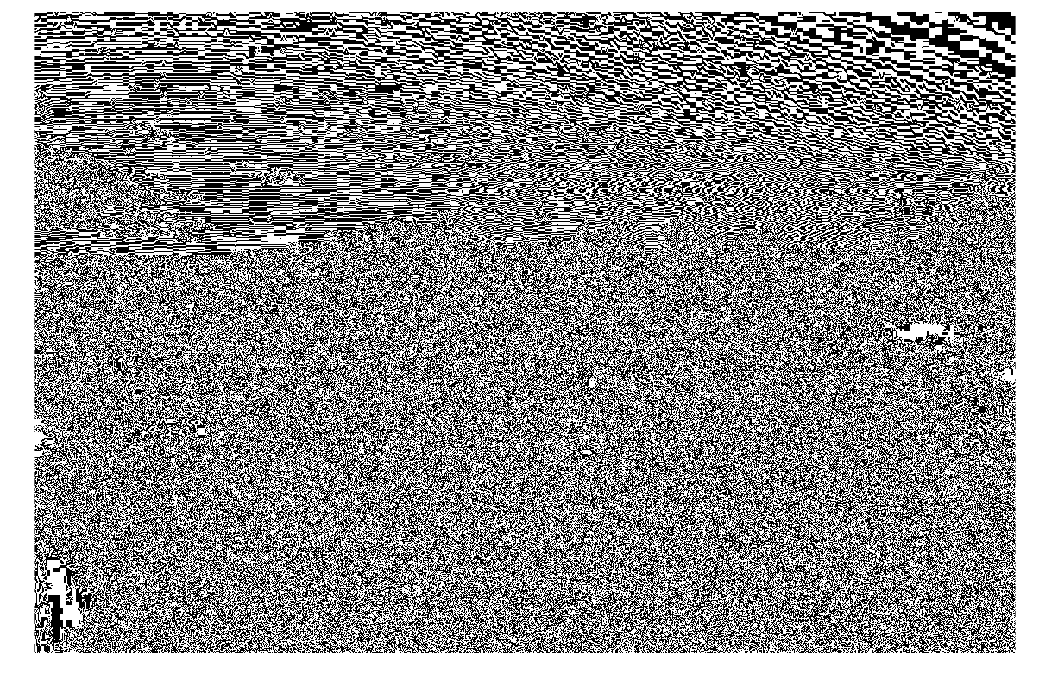

mask = logical(bitget(roomGSImg, 1));
imshow(mask)

Now, use the `bitset` command to set the least significant bit to that of the QUT logo.

secret = bitset(roomGSImg, 1, qutLogoImg);

Save the resulting array as a new image file.

imwrite(secret, "secret.png")

Now read in the image file you just saved into a new array.

secretImage = imread("secret.png");

Visualise the new array to confirm it looks like an ordinary greyscale image, with no hint of any hidden information.

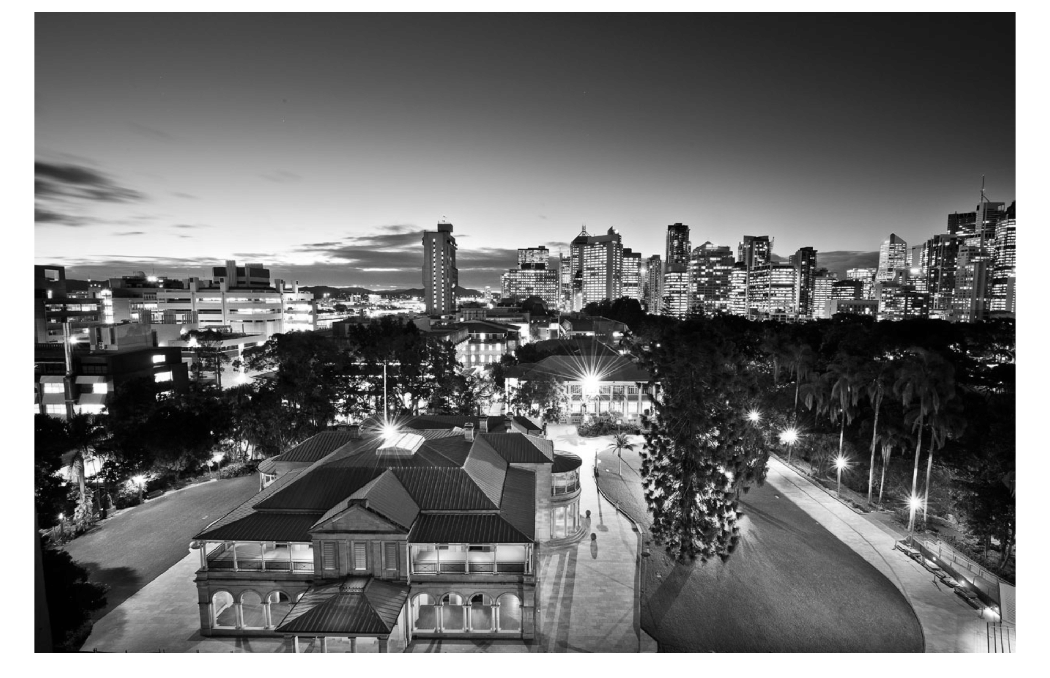

imshow(secretImage)

But now extract the information hidden in the least significant bit, to confirm that it reveals the QUT logo!

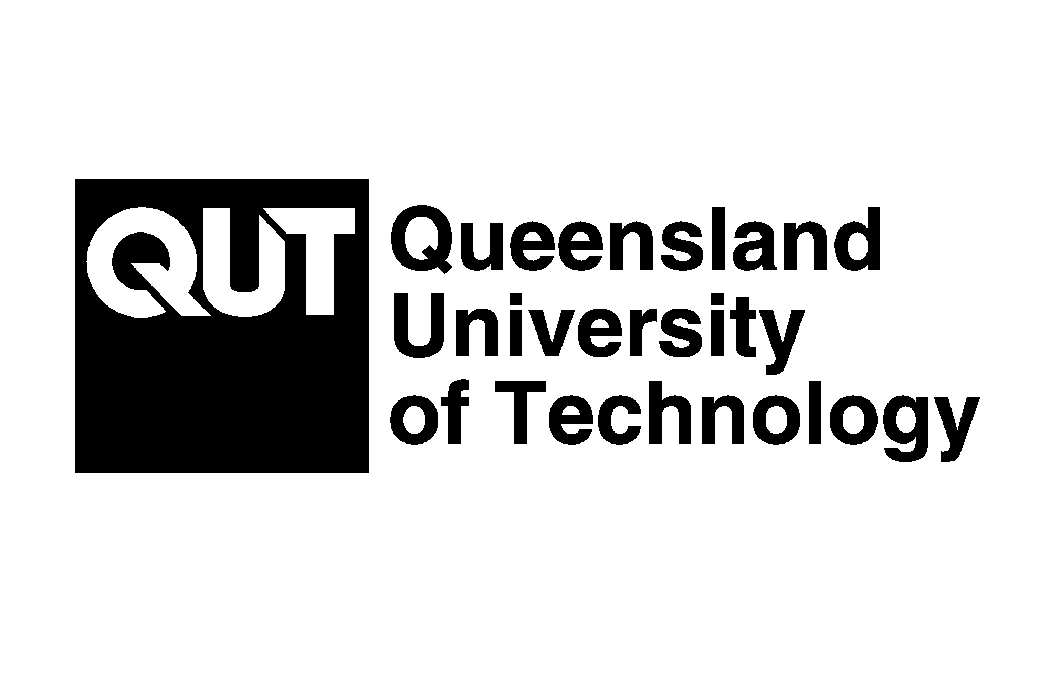

imshow(logical(bitget(secretImage, 1)))

**Well done on finishing this section**.  Now you can continue on to the exercises.

# Exercises

1. Create your own greyscale and RGB colour sliders, to replicate those from the lecture.

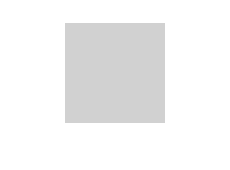

gs = 0.82;
r = 190;
g = 86;
b = 245;

U = zeros(100,100);
U(:) = gs;
imshow(U)

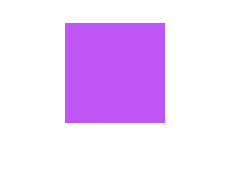

J = uint8(zeros(100, 100, 3));
J(:, :, 1) = r;
J(:, :, 2) = g;
J(:, :, 3) = b;
imshow(J)

2. Experiment with creating masks to pick out the green balloon and the yellow balloon from section 3.5.  You will probably find it's still difficult to get a precise result for these balloons, so don't be disappointed if bits of string, or outlines of the other balloons remain despite your best efforts.  We will revisit this next week and learn ways to tidy up the masks to remove this noise.

imshow(balloons(:,:,1) > 80 & balloons(:,:,2) < 100 & balloons(:,:,3) < 100)

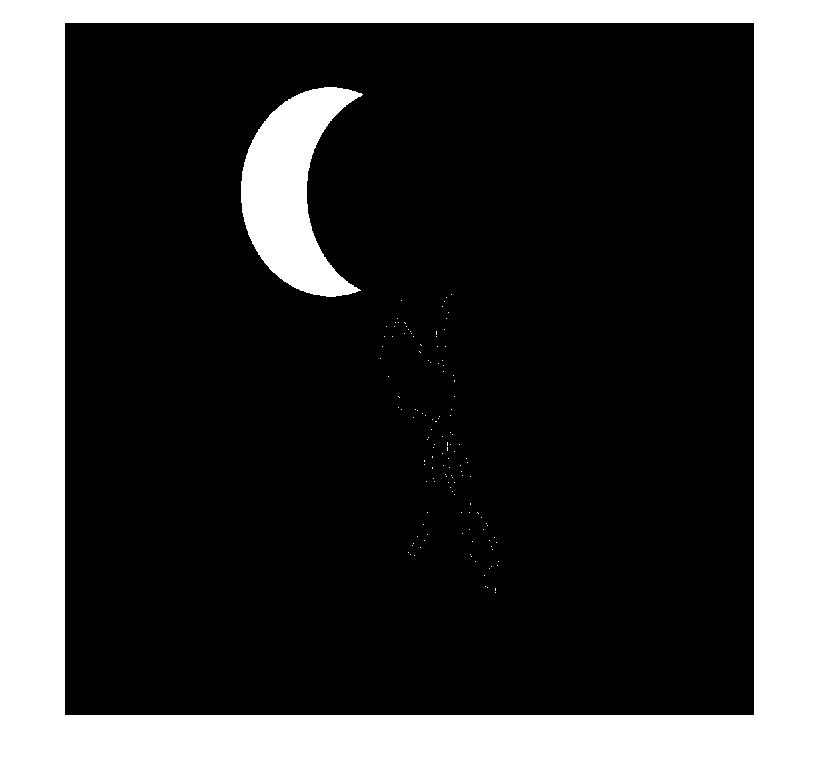

imshow(balloons(:,:,1) < 130 & balloons(:,:,2) > 100 & balloons(:,:,3) < 130)

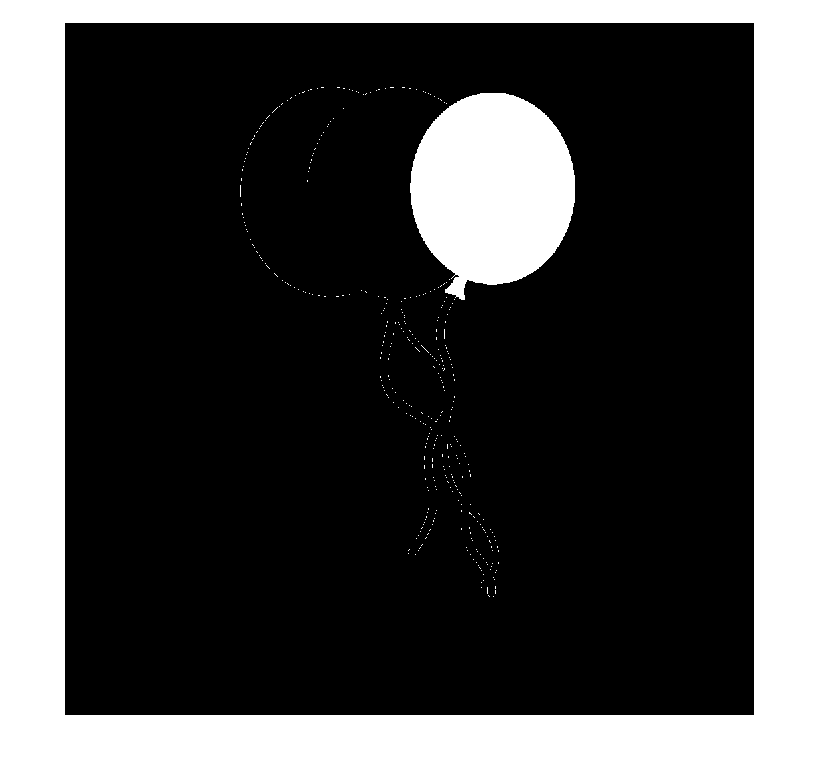

imshow(balloons(:,:,1) > 120 & balloons(:,:,2) > 120 & balloons(:,:,3) < 200)

# Quiz

The Quiz is your assessment for this topic.  The link can be found on Canvas on the Topic 3 - Image Processing 1 page.  Follow the link to complete the Quiz.